# yolov5-matlab

TheMatrix   cuixingxing150@gmail.com

Import yolov5*.onnx for inference, including yolov5s.onnx, yolov5m.onnx, yolov5l.onnx, yolov5x.onnx, the original output dimension is 1*255*H*W(Other dimension formats can be slightly modified), import (importONNXFunction) + detection in matlab Head decoding output.

导入yolov5*.onnx进行推理（inference），包括yolov5s.onnx,yolov5m.onnx,yolov5l.onnx,yolov5x.onnx,其原始输出维度为1*255*H*W(其他维度形式可稍作修改), 在matlab中导入(importONNXFunction)+检测头解码输出。

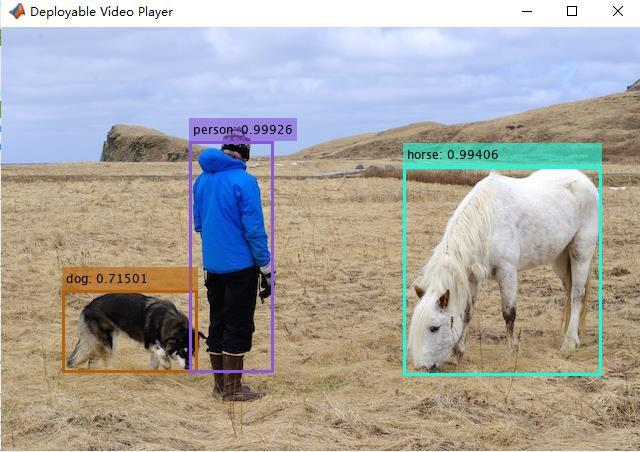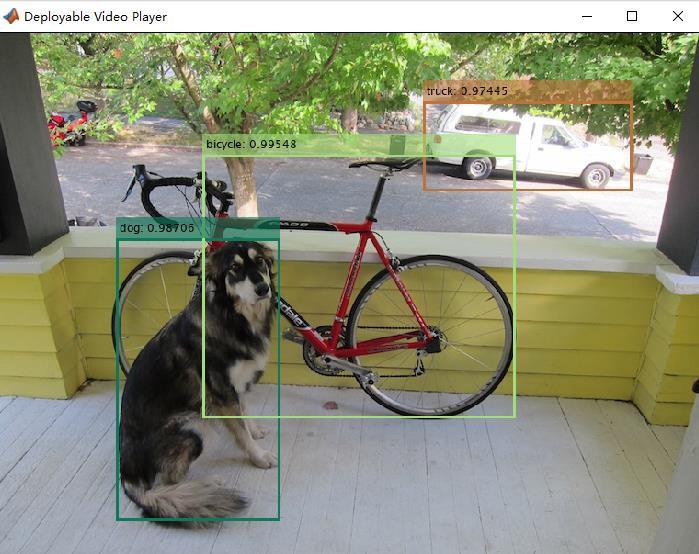

## Requirements

Matlab R2021a or higher,the newer the better,no other dependencies.

## import model

model = "./onnxPretrainedModels/"+"yolov5s.onnx";
customYoloV5FcnName = 'yolov5fcn';
inputSize = [640,640];
throushHold = 0.3;
nmsThroushHold = 0.5;
outs = cell(3,1); % 3个检测head输出
classesNames = categorical(readlines("coco.names"));
colors = randi(255,length(classesNames),3);
params = importONNXFunction(model,customYoloV5FcnName);

Function containing the imported ONNX network architecture was saved to the file yolov5fcn.m.
To learn how to use this function, type: help yolov5fcn.


## 摄像头视频流识别

cap = webcam();
player = vision.DeployableVideoPlayer();
image = cap.snapshot(); % image = imread('images/person.jpg');
step(player, image);
[H,W,~] = size(image);
while player.isOpen()
    image = cap.snapshot(); % image = imread('images/person.jpg');
    img = imresize(image,inputSize);
    img = rescale(img,0,1);% 转换到[0,1]
    img = permute(img,[3,1,2]);
    img = dlarray(reshape(img,[1,size(img)])); % n*c*h*w，[0,1],RGB顺序
    if canUseGPU()
        img = gpuArray(img);
    end
    t1 = tic;
    [outs{:}] = feval(customYoloV5FcnName,img,params,...
        'Training',false,...
        'InputDataPermutation','none',...
        'OutputDataPermutation','none');% or call the function directly
    fprintf('yolov5预测耗时：%.2f 秒\n',toc(t1));% yolov5s大概0.25秒，yolov5m大概0.75秒，yolov5l大概1.49秒，yolov5x大概2.81秒
    
    outFeatures = yolov5Decode(outs,H,W);

yolov5预测耗时：0.65 秒
yolov5预测耗时：0.30 秒
yolov5预测耗时：0.28 秒
yolov5预测耗时：0.28 秒
yolov5预测耗时：0.39 秒
yolov5预测耗时：0.26 秒
yolov5预测耗时：0.26 秒
yolov5预测耗时：0.25 秒
yolov5预测耗时：0.26 秒
yolov5预测耗时：0.26 秒
yolov5预测耗时：0.26 秒
yolov5预测耗时：0.26 秒
yolov5预测耗时：0.26 秒
yolov5预测耗时：0.26 秒
yolov5预测耗时：0.26 秒


## 阈值过滤+NMS处理

    scores = outFeatures(:,5);
    outFeatures = outFeatures(scores>throushHold,:);
    
    allBBoxes = outFeatures(:,1:4);
    [maxScores,indxs] = max(outFeatures(:,6:end),[],2);
    allScores = maxScores;
    allLabels = classesNames(indxs);
    
    % NMS非极大值抑制
    if ~isempty(allBBoxes)
        [bboxes,scores,labels] = selectStrongestBboxMulticlass(allBBoxes,allScores,allLabels,...
            'RatioType','Min','OverlapThreshold',nmsThroushHold);
        annotations = string(labels) + ": " + string(scores);
        [~,ids] = ismember(labels,classesNames);
        color = colors(ids,:);
        image = insertObjectAnnotation(image,...
            'rectangle',bboxes,cellstr(annotations),...
            'Color',color,...
            'LineWidth',3);
    end
    step(player,image);
end
release(player);

## support function

function outPutFeatures = yolov5Decode(featuremaps,oriHight,oriWidth,anchors)
% 功能：根据anchors对yolov5.onnx原始输出特征图进行解码，直接获得解码后的输出特征矩阵
% 输入：
%      featuremaps：  numHeads*1大小的cell，每个cell保存当前检测头的featuremap,为bs*[(4+1+nc)*na]*h*w大小特征图矩阵
%      oriHight:原始输入图像的高
%      oriWidth:原始输入图像的宽
%      anchors： 对应模型yolov5.onnx的所有anchors,na*2大小，每行形如[width,height]顺序排列，na为anchors的数量
% 输出：
%     outPutFeatures： M*(5+nc)或者bs*M*(5+nc)大小
%     ,为bs*M*[x,y,w,h,Pobj,p1,p2,...,pn]大小的形式矩阵，如果是单张图像检测，则输出大小为M*(5+nc)，否则是bs*M*(5+nc),
%     其中，M为检测框的数量，bs为图片数量，nc为训练网络dlnet类别数量，x,y,w,h分别是输入图片上对应的x,y,width,height，Pobj
%     为物体概率，p1,p2,...,pn分别为对应coco.names类别概率
% 注意：
% 1、假设yolov5.onnx输入图像大小为1*3*640*640,[0,1]范围float，RGB顺序；
% 2、输出有3个head,每个head大小形如为1*255*gh*gw，其中gh,gw分别表示特征图高和宽，255表示na*[cx,cy,w,h,Pobj,p1,p2,...pn]顺序含义；
% 3、小值的anchor对应原始输出的大特征图，大值的anchor对应原始输出的小特征图，anchors“从小到大”顺序传入，3个anchor为一组；
% 4、每一个检测head对应3个anchor
% 5、检测目标类别数量为coco中的80
%  其他onnx模型格式类推，大同小异
%
% reference:
% 1、https://github.com/cuixing158/yolov3-yolov4-matlab/blob/master/utils/yolov3v4Predict.m
% 2、https://github.com/ultralytics/yolov5/blob/master/models/yolo.py
% 3、https://github.com/onnx/models
%
% author: cuixingxing
% email:cuixingxing150@gmail.com
% 2021.3.17创建
%
arguments
    featuremaps (:,1) cell
    oriHight (1,1) double
    oriWidth (1,1) double
    anchors (:,2) double = [10,13; 16,30; 33,23;...
        30,61; 62,46; 59,119;...
        116,90; 156,198; 373,326]
end

## yolov5*.onnx known params

inputSize = 640;%输入网络图像大小，正方形图像输入
na = 3;% 每个检测head对应anchor的数量
nc = 80; % coco类别数量

## decode

scaledX = inputSize./oriWidth;
scaledY = inputSize./oriHight;
outPutFeatures = [];
numberFeaturemaps = length(featuremaps);
for i = 1:numberFeaturemaps
    currentFeatureMap = featuremaps{i};% bs*[(4+1+nc)*na]*h*w大小
    currentAnchors = anchors(na*(i-1)+1:na*i,:); % na*2
    numY = size(currentFeatureMap,3);
    numX = size(currentFeatureMap,4);
    stride = inputSize./numX;
    
    % reshape currentFeatureMap到有意义的维度，bs*[(4+1+nc)*na]*h*w --> h*w*(5+nc)*na*bs
    % --> bs*na*h*w*(5+nc),最终的维度方式与yolov5官网兼容
    bs = size(currentFeatureMap,1);
    h = numY;
    w = numX;
    currentFeatureMap = reshape(currentFeatureMap,bs,5+nc,na,h,w);% bs*(5+nc)*na*h*w
    currentFeatureMap = permute(currentFeatureMap,[1,3,4,5,2]);%  bs*na*h*w*(5+nc)
 
    [~,~,yv,xv] = ndgrid(1:bs,1:na,0:h-1,0:w-1);% yv,xv大小都为bs*na*h*w，注意顺序，后面做加法维度标签要对应
    gridXY = cat(5,xv,yv);% 第5维上扩展，大小为bs*na*h*w*2, x,y从1开始的索引
    currentFeatureMap = sigmoid(currentFeatureMap); % yolov5是对所有值进行归一化，与yolov3/v4不同
    currentFeatureMap(:,:,:,:,1:2) = (2*currentFeatureMap(:,:,:,:,1:2)-0.5 + gridXY).*stride; % 大小为bs*na*h*w*2,预测对应xy
    anchor_grid = reshape(currentAnchors,1,na,1,1,2);% 此处anchor_grid大小为1*na*1*1*2，方便下面相乘
    currentFeatureMap(:,:,:,:,3:4) = (currentFeatureMap(:,:,:,:,3:4)*2).^2.*anchor_grid;% 大小为bs*na*h*w*2
    
    if nc == 1
        currentFeatureMap(:,:,:,:,6) = 1;
    end
    currentFeatureMap = reshape(currentFeatureMap,bs,[],5+nc);% bs*N*(5+nc)
    
    if isempty(outPutFeatures)
        outPutFeatures = currentFeatureMap;
    else
        outPutFeatures = cat(2,outPutFeatures,currentFeatureMap);% bs*M*(5+nc)
    end
end

## 坐标转换到原始图像上

[cx,cy,w,h]，yolov5.onnx基准图像大小（1*3*640*640）----> [x,y,w,h],坐标基于原始图像大小（1*3*oriHight*oriWidth）

outPutFeatures = extractdata(outPutFeatures);% bs*M*(5+nc) ,为[x_center,y_center,w,h,Pobj,p1,p2,...,pn]
outPutFeatures(:,:,[1,3]) = outPutFeatures(:,:,[1,3])./scaledX;% x_center,width
outPutFeatures(:,:,[2,4]) = outPutFeatures(:,:,[2,4])./scaledY;% y_center,height
outPutFeatures(:,:,1) = outPutFeatures(:,:,1) -outPutFeatures(:,:,3)/2;%  x
outPutFeatures(:,:,2) = outPutFeatures(:,:,2) -outPutFeatures(:,:,4)/2; % y

outPutFeatures = squeeze(outPutFeatures); % 如果是单张图像检测，则输出大小为M*(5+nc)，否则是bs*M*(5+nc)
if(canUseGPU())
    outPutFeatures = gather(outPutFeatures); % 推送到CPU上
end
end

## Reference:

[1] [yolov3-yolov4-matlab](https://github.com/cuixing158/yolov3-yolov4-matlab/blob/master/utils/yolov3v4Predict.m)

[2] [yolov5](https://github.com/ultralytics/yolov5/blob/master/models/yolo.py)

[3] [onnxModels](https://github.com/onnx/models)